# Minimum Mean Square Error Equalizer

% Uplink
% Achievable Rate V.S. Correlation Parameter
% Linear Formation and Rectangular Formation

## Global Parameter

clc
clearvars

% Number of Antennas and Users
M1 = 8;
M2 = 8;
M = M1 * M2;
K = 10;

% Channel Length
taps = 4;

% Block Length
time = 100;

% Cyclic Prefix Length
cyclic = 20;

% Channel Uses
use = 5;

% Freuqency Length
freq = 20;

% Normalized Distance
dn = 0.5;

% Power
r = 10;
e = 10 * log10(r);

% Correlation Parameters
alpha = [0.0, 0.4, 0.7, 0.9, 0.99];
eta = [0, 50, 100, 200, 500];
mu = [0.0, pi / 6, pi / 4, pi / 3, pi / 2];

sample = 5;


## Correlation Matrix

% Linear
for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end

fix_eta = 50;
fix_mu = 0;

for index = 1 : sample
    corr_exp_1d(:, :, index) = alpha(index) .^ dist;
    arg = fix_eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * fix_eta * sin(mu(index)) .* dist;
    arg = sqrt(arg);
    corr_bsl_1d_mu(:, :, index) = besseli(0, arg) ./ besseli(0, fix_eta);
    arg = eta(index) ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta(index) * sin(fix_mu) .* dist;
    arg = sqrt(arg);
    corr_bsl_1d_eta(:, :, index) = besseli(0, arg) ./ besseli(0, eta(index));
end
clear dist;

% Rectangular
i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end

for index = 1 : sample
    dist = sqrt(dist .* dn);
    corr_exp_2d(:, :, index) = alpha(index) .^ dist;
    arg = fix_eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * fix_eta * sin(mu(index)) .* dist;
    arg = sqrt(arg);
    corr_bsl_2d_mu(:, :, index) = besseli(0, arg) ./ besseli(0, fix_eta);
    arg = eta(index) ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta(index) * sin(fix_mu) .* dist;
    arg = sqrt(arg);
    corr_bsl_2d_eta(:, :, index) = besseli(0, arg) ./ besseli(0, eta(index));
end
clear dist;


## Channel Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for index = 1 : sample
    
    exp_1D = corr_exp_1d(:, :, index);
    bsl_1D_mu = corr_bsl_1d_mu(:, :, index);
    bsl_1D_eta = corr_bsl_1d_eta(:, :, index);
    exp_2D = corr_exp_2d(:, :, index);
    bsl_2D_mu = corr_bsl_2d_mu(:, :, index);
    bsl_2D_eta = corr_bsl_2d_eta(:, :, index);
    
    for n = 1 : use
        S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
        Z(:, :, n) = (sqrt(0.5)) * (randn(M, time + cyclic) + 1i * randn(M, time + cyclic));
        
        for l = 1 : taps
            D1 = D(:, :, l) .^ (0.5);
            H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
            Hl_exp_1D(:, :, l, n) = (exp_1D ^ (0.5)) * H1 * D1;
            Hl_bsl_1D_mu(:, :, l, n) = (bsl_1D_mu ^ (0.5)) * H1 * D1;
            Hl_bsl_1D_eta(:, :, l, n) = (bsl_1D_eta ^ (0.5)) * H1 * D1;
            Hl_exp_2D(:, :, l, n) = (exp_2D ^ (0.5)) * H1 * D1;
            Hl_bsl_2D_mu(:, :, l, n) = (bsl_2D_mu ^ (0.5)) * H1 * D1;
            Hl_bsl_2D_eta(:, :, l, n) = (bsl_2D_eta ^ (0.5)) * H1 * D1;
        end
        
        Hv1 = fft(Hl_exp_1D(:, :, :, n), freq, 3);
        Hv2 = fft(Hl_bsl_1D_mu(:, :, :, n), freq, 3);
        Hv3 = fft(Hl_bsl_1D_eta(:, :, :, n), freq, 3);
        Hv4 = fft(Hl_exp_2D(:, :, :, n), freq, 3);
        Hv5 = fft(Hl_bsl_2D_mu(:, :, :, n), freq, 3);
        Hv6 = fft(Hl_bsl_2D_eta(:, :, :, n), freq, 3);
        
        if (0 <= alpha(index)) && (alpha(index) < 0.4)
            beta = 14;
        elseif (0.4 <= alpha(index)) && (alpha(index) < 0.7)
            beta = 10.7;
        elseif (0.7 <= alpha(index)) && (alpha(index) < 0.9)
            beta = 8.5;
        elseif (0.9 <= alpha(index)) && (alpha(index) < 0.99)
            beta = 2;
        else
            beta = 0.5;
        end
        for v = 1 : freq
            Fv = Hv1(:, :, v);
            Qv1(:, :, v, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv2(:, :, v);
            Qv2(:, :, v, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv3(:, :, v);
            Qv3(:, :, v, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv4(:, :, v);
            Qv4(:, :, v, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv5(:, :, v);
            Qv5(:, :, v, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv6(:, :, v);
            Qv6(:, :, v, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
        end
        Ql_exp_1D(:, :, :, n) = ifft(Qv1(:, :, :, n), freq, 3);
        Ql_bsl_1D_mu(:, :, :, n) = ifft(Qv2(:, :, :, n), freq, 3);
        Ql_bsl_1D_eta(:, :, :, n) = ifft(Qv3(:, :, :, n), freq, 3);
        Ql_exp_2D(:, :, :, n) = ifft(Qv4(:, :, :, n), freq, 3);
        Ql_bsl_2D_mu(:, :, :, n) = ifft(Qv5(:, :, :, n), freq, 3);
        Ql_bsl_2D_eta(:, :, :, n) = ifft(Qv6(:, :, :, n), freq, 3);
        
        [AQ1(n)] = Signal_Power(taps, Ql_exp_1D(:, :, :, n));
        [AQ2(n)] = Signal_Power(taps, Ql_bsl_1D_mu(:, :, :, n));
        [AQ3(n)] = Signal_Power(taps, Ql_bsl_1D_eta(:, :, :, n));
        [AQ4(n)] = Signal_Power(taps, Ql_exp_2D(:, :, :, n));
        [AQ5(n)] = Signal_Power(taps, Ql_bsl_2D_mu(:, :, :, n));
        [AQ6(n)] = Signal_Power(taps, Ql_bsl_2D_eta(:, :, :, n));
        
        for l = 1 : taps
            E1(:, :, l, n) = (Ql_exp_1D(:, :, l, n)) * (Hl_exp_1D(:, :, l, n));
            E2(:, :, l, n) = (Ql_bsl_1D_mu(:, :, l, n)) * (Hl_bsl_1D_mu(:, :, l, n));
            E3(:, :, l, n) = (Ql_bsl_1D_eta(:, :, l, n)) * (Hl_bsl_1D_eta(:, :, l, n));
            E4(:, :, l, n) = (Ql_exp_2D(:, :, l, n)) * (Hl_exp_2D(:, :, l, n));
            E5(:, :, l, n) = (Ql_bsl_2D_mu(:, :, l, n)) * (Hl_bsl_2D_mu(:, :, l, n));
            E6(:, :, l, n) = (Ql_bsl_2D_eta(:, :, l, n)) * (Hl_bsl_2D_eta(:, :, l, n));
        end
    end
    
    an1 = 1 / mean(AQ1);
    an2 = 1 / mean(AQ2);
    an3 = 1 / mean(AQ3);
    an4 = 1 / mean(AQ4);
    an5 = 1 / mean(AQ5);
    an6 = 1 / mean(AQ6);
    
    for n = 1 : use
        for k = 1 : K
            for l = 1 : taps
                gk1(k, :, n, l) = E1(k, k, l, n) * S(k, :, n);
                gk2(k, :, n, l) = E2(k, k, l, n) * S(k, :, n);
                gk3(k, :, n, l) = E3(k, k, l, n) * S(k, :, n);
                gk4(k, :, n, l) = E4(k, k, l, n) * S(k, :, n);
                gk5(k, :, n, l) = E5(k, k, l, n) * S(k, :, n);
                gk6(k, :, n, l) = E6(k, k, l, n) * S(k, :, n);
            end
        end
    end
    
    gi1 = sum(gk1, 4);
    gi2 = sum(gk2, 4);
    gi3 = sum(gk3, 4);
    gi4 = sum(gk4, 4);
    gi5 = sum(gk5, 4);
    gi6 = sum(gk6, 4);
    
    xi = S;
    for j = 1 : cyclic
        xi(:, time + j, :) = xi(:, j, :);
    end

    for n = 1 : use
        for l = 1 : taps
            for j = 0 : time + cyclic - 1
                rl1(:, j + 1, n, l) = (Hl_exp_1D(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
                rl2(:, j + 1, n, l) = (Hl_bsl_1D_mu(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
                rl3(:, j + 1, n, l) = (Hl_bsl_1D_eta(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
                rl4(:, j + 1, n, l) = (Hl_exp_2D(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
                rl5(:, j + 1, n, l) = (Hl_bsl_2D_mu(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
                rl6(:, j + 1, n, l) = (Hl_bsl_2D_eta(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
            end
        end
    end
    
    temp = sum(rl1, 4);
    Rf1 = fft(temp, freq, 2);
    clear temp;
    temp = sum(rl2, 4);
    Rf2 = fft(temp, freq, 2);
    clear temp;
    temp = sum(rl3, 4);
    Rf3 = fft(temp, freq, 2);
    clear temp;
    temp = sum(rl4, 4);
    Rf4 = fft(temp, freq, 2);
    clear temp;
    temp = sum(rl5, 4);
    Rf5 = fft(temp, freq, 2);
    clear temp;
    temp = sum(rl6, 4);
    Rf6 = fft(temp, freq, 2);
    clear temp;
    
    for n = 1 : use
        for v = 1 : freq
            Yf1(:, v, n) = Qv1(:, :, v, n) * Rf1(:, v, n);
            Yf2(:, v, n) = Qv2(:, :, v, n) * Rf2(:, v, n);
            Yf3(:, v, n) = Qv3(:, :, v, n) * Rf3(:, v, n);
            Yf4(:, v, n) = Qv4(:, :, v, n) * Rf4(:, v, n);
            Yf5(:, v, n) = Qv5(:, :, v, n) * Rf5(:, v, n);
            Yf6(:, v, n) = Qv6(:, :, v, n) * Rf6(:, v, n);
        end
    end
    
    yi1 = ifft(Yf1, time, 2);
    yi2 = ifft(Yf2, time, 2);
    yi3 = ifft(Yf3, time, 2);
    yi4 = ifft(Yf4, time, 2);
    yi5 = ifft(Yf5, time, 2);
    yi6 = ifft(Yf6, time, 2);
    
    ni1 = yi1 - gi1;
    ni2 = yi2 - gi2;
    ni3 = yi3 - gi3;
    ni4 = yi4 - gi4;
    ni5 = yi5 - gi5;
    ni6 = yi6 - gi6;
    
    for n = 1 : use
        for m = 1 : freq
            for j = 0 : time + cyclic - 1
                tm1(:, n, j + 1, m) = an1 * Ql_exp_1D(:, :, m, n) * Z(:, mod(j - m, time) + 1, n);
                tm2(:, n, j + 1, m) = an2 * Ql_bsl_1D_mu(:, :, m, n) * Z(:, mod(j - m, time) + 1, n);
                tm3(:, n, j + 1, m) = an3 * Ql_bsl_1D_eta(:, :, m, n) * Z(:, mod(j - m, time) + 1, n);
                tm4(:, n, j + 1, m) = an4 * Ql_exp_2D(:, :, m, n) * Z(:, mod(j - m, time) + 1, n);
                tm5(:, n, j + 1, m) = an5 * Ql_bsl_2D_mu(:, :, m, n) * Z(:, mod(j - m, time) + 1, n);
                tm6(:, n, j + 1, m) = an6 * Ql_bsl_2D_eta(:, :, m, n) * Z(:, mod(j - m, time) + 1, n);
            end
        end
    end
    
    ti = sum(tm1, 4);
    AWGN1 = mean(var(ti, 0, 3), 2);
    clear ti;
    ti = sum(tm2, 4);
    AWGN2 = mean(var(ti, 0, 3), 2);
    clear ti;
    ti = sum(tm3, 4);
    AWGN3 = mean(var(ti, 0, 3), 2);
    clear ti;
    ti = sum(tm4, 4);
    AWGN4 = mean(var(ti, 0, 3), 2);
    clear ti;
    ti = sum(tm5, 4);
    AWGN5 = mean(var(ti, 0, 3), 2);
    clear ti;
    ti = sum(tm6, 4);
    AWGN6 = mean(var(ti, 0, 3), 2);
    clear ti;
    
    E1_sum = sum(mean(E1, 4), 3);
    E2_sum = sum(mean(E2, 4), 3);
    E3_sum = sum(mean(E3, 4), 3);
    E4_sum = sum(mean(E4, 4), 3);
    E5_sum = sum(mean(E5, 4), 3);
    E6_sum = sum(mean(E6, 4), 3);
    
    for n = 1 : use
        for k = 1 : K
            Sk1 = abs(an1 * (E1_sum(k, k))) ^ 2 * r;
            Sk2 = abs(an2 * (E2_sum(k, k))) ^ 2 * r;
            Sk3 = abs(an3 * (E3_sum(k, k))) ^ 2 * r;
            Sk4 = abs(an4 * (E4_sum(k, k))) ^ 2 * r;
            Sk5 = abs(an5 * (E5_sum(k, k))) ^ 2 * r;
            Sk6 = abs(an2 * (E6_sum(k, k))) ^ 2 * r;
            
            Sn1 = var(ni1(k, :, n), 0, 2) * r + AWGN1(k);
            Sn2 = var(ni2(k, :, n), 0, 2) * r + AWGN2(k);
            Sn3 = var(ni3(k, :, n), 0, 2) * r + AWGN3(k);
            Sn4 = var(ni4(k, :, n), 0, 2) * r + AWGN4(k);
            Sn5 = var(ni5(k, :, n), 0, 2) * r + AWGN5(k);
            Sn6 = var(ni6(k, :, n), 0, 2) * r + AWGN6(k);
           
            SNR1 = Sk1 / Sn1;
            SNR2 = Sk2 / Sn2;
            SNR3 = Sk3 / Sn3;
            SNR4 = Sk4 / Sn4;
            SNR5 = Sk5 / Sn5;
            SNR6 = Sk6 / Sn6;
            
            Rk1(k, :, n) = log2(1 + SNR1);
            Rk2(k, :, n) = log2(1 + SNR2);
            Rk3(k, :, n) = log2(1 + SNR3);
            Rk4(k, :, n) = log2(1 + SNR4);
            Rk5(k, :, n) = log2(1 + SNR5);
            Rk6(k, :, n) = log2(1 + SNR6);
        end
    end
    
    R1(index) = 0.5 * mean(sum(Rk1, 1), 3);
    R2(index) = 0.5 * mean(sum(Rk2, 1), 3);
    R3(index) = 0.5 * mean(sum(Rk3, 1), 3);
    R4(index) = 0.5 * mean(sum(Rk4, 1), 3);
    R5(index) = 0.5 * mean(sum(Rk5, 1), 3);
    R6(index) = 0.5 * mean(sum(Rk6, 1), 3);
    
    clear Hl_exp_1D Hl_bsl_1D_mu Hl_bsl_1D_eta Hl_exp_2D Hl_bsl_2D_mu Hl_bsl_2D_eta;
    clear Ql_exp_1D Ql_bsl_1D_mu Ql_bsl_1D_eta Ql_exp_2D Ql_bsl_2D_mu Ql_bsl_2D_eta;
    
    clear E1_sum E2_sum E3_sum E4_sum E5_sum E6_sum;
    clear ni1 ni2 ni3 ni4 ni5 ni6;
    clear AWGN1 AWGN2 AWGN3 AWGN4 AWGN5 AWGN6;
    clear Rk1 Rk2 Rk3 Rk4 Rk5 Rk6;
    clear S Z;
    
end
    
factor = (time) / (time + cyclic);
    
R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;
R5 = factor * R5;
R6 = factor * R6;


## Visualization

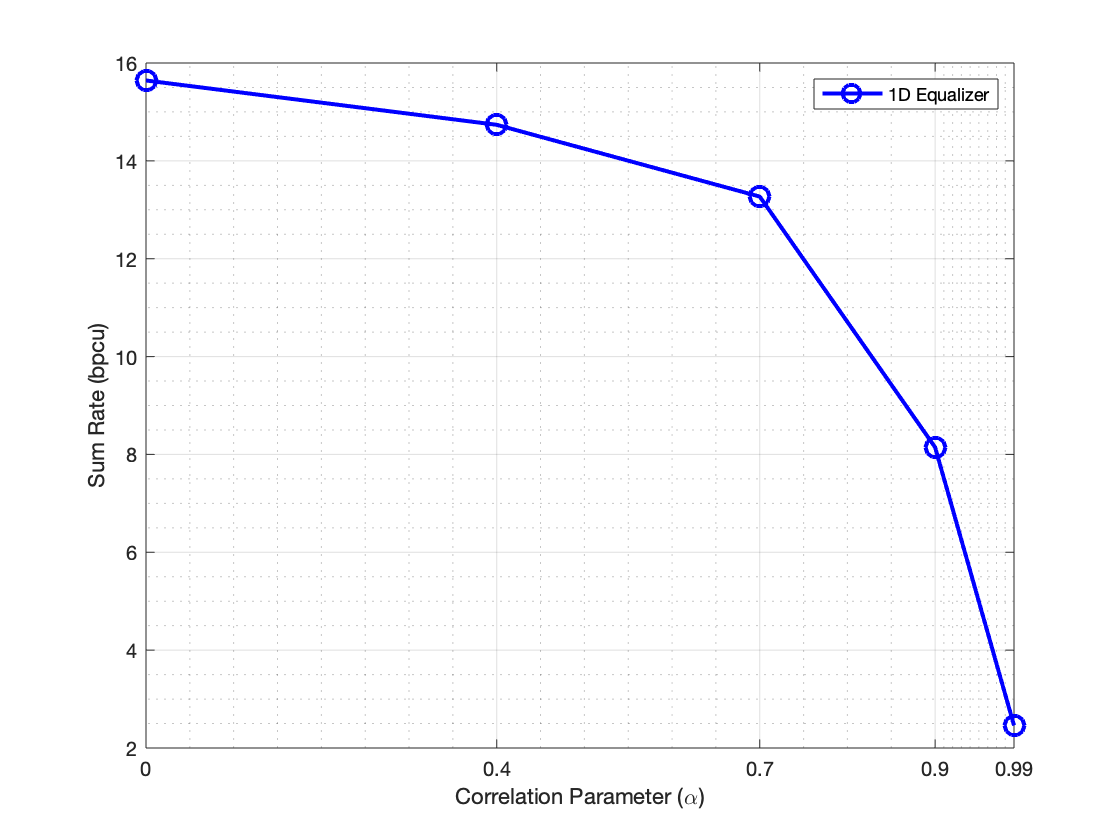

name_a = '1D Equalizer';
name_b = '2D Equalizer';

name1 = name_a;
name2 = strcat(name_a, ', \eta=', num2str(fix_eta));
name3 = strcat(name_a, ', \mu=', num2str(fix_mu));
name4 = name_b;
name5 = strcat(name_b, ', \eta=', num2str(fix_eta));
name6 = strcat(name_b, ', \mu=', num2str(fix_mu));

x_label_1 = 'Correlation Parameter (\alpha)';
x_label_2 = 'Correlation Parameter (\mu)';
x_label_3 = 'Correlation Parameter (\eta)';
y_label = 'Sum Rate (bpcu)';

style_1 = '-bo';
style_2 = '-ro';

figure;
plot(alpha, R1, style_1, 'DisplayName', name1, 'MarkerSize', 10);

xlabel(x_label_1, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(alpha);
xlim([alpha(1), alpha(sample)]);
legend();
grid on;
grid minor;

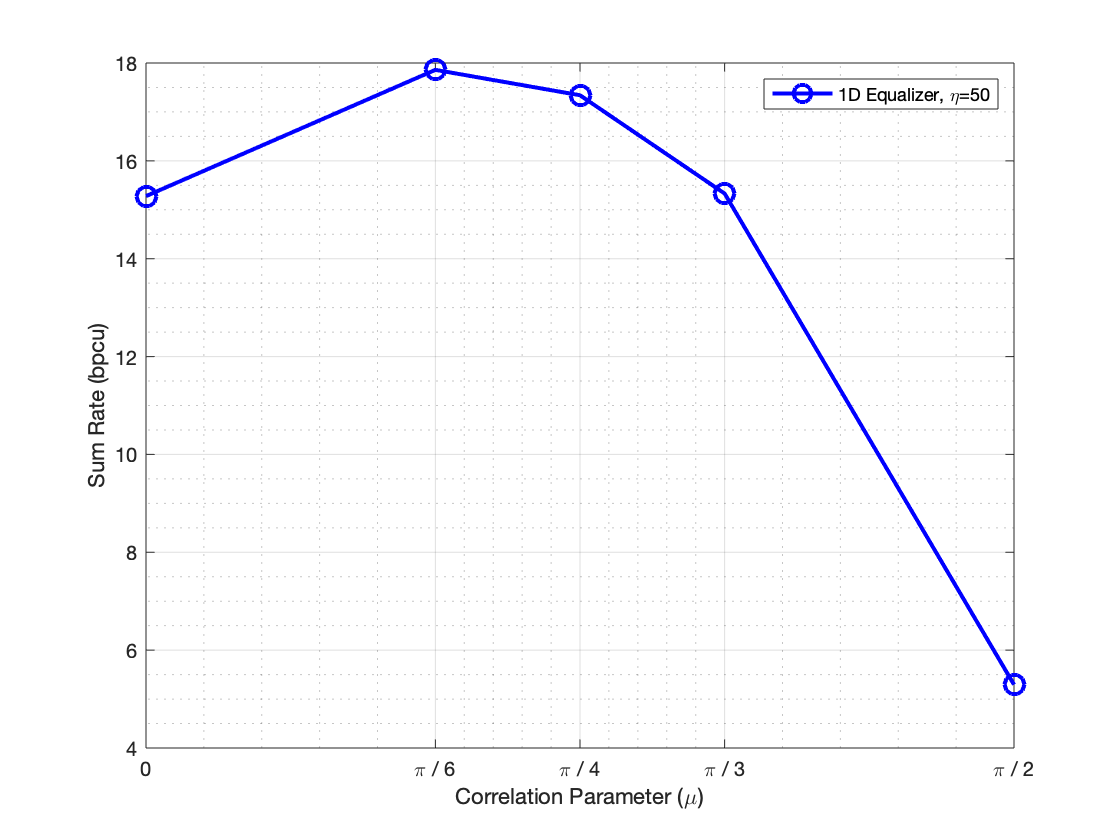



figure;
plot(mu, R2, style_1, 'DisplayName', name2, 'MarkerSize', 10);

xlabel(x_label_2, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(mu);
xticklabels({'0', '\pi / 6', '\pi / 4', '\pi / 3', '\pi / 2'})
xlim([mu(1), mu(sample)]);
legend();
grid on;
grid minor;

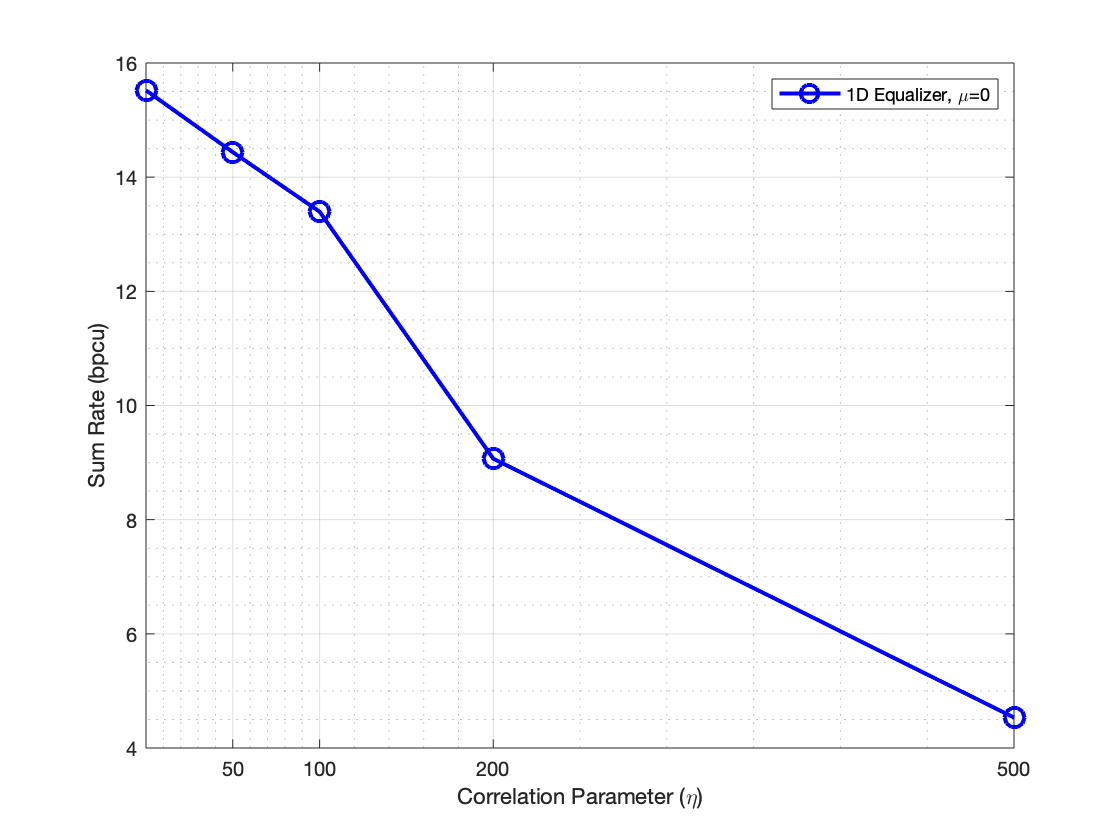



figure;
plot(eta, R3, style_1, 'DisplayName', name3, 'MarkerSize', 10);

xlabel(x_label_3, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(eta(2 : sample));
xlim([eta(1), eta(sample)]);
legend();
grid on;
grid minor;

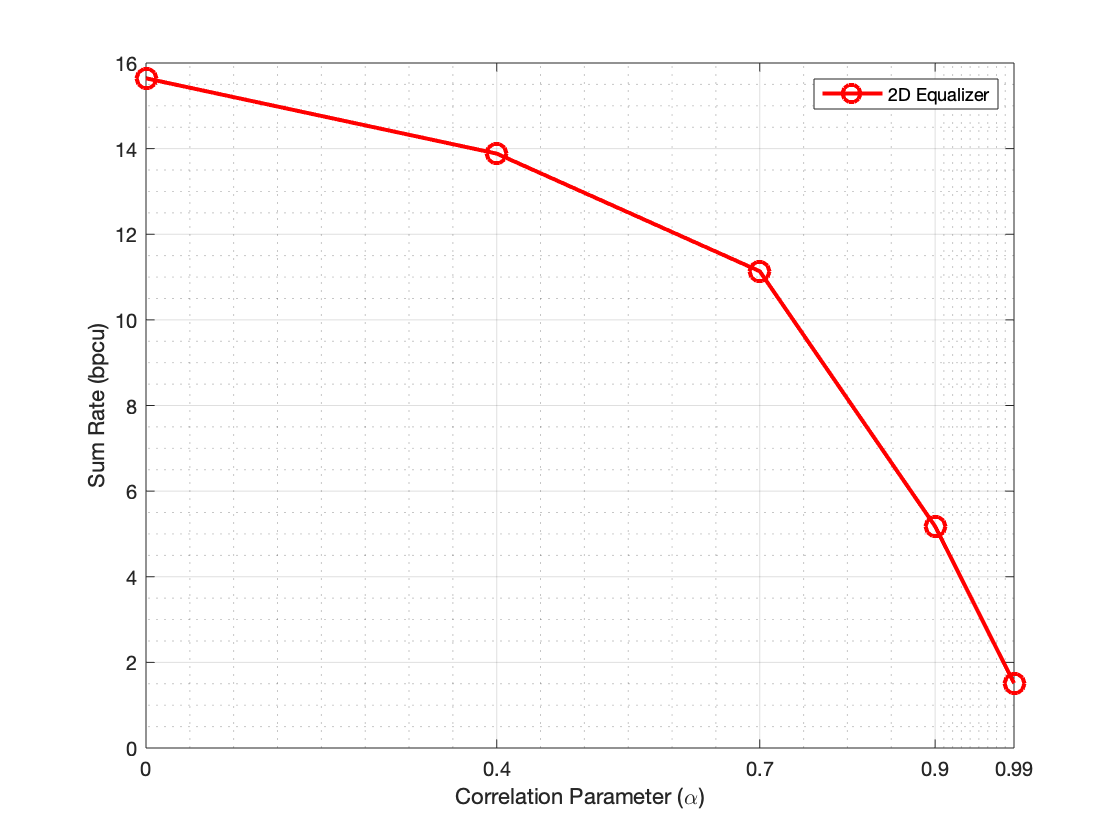


figure;
plot(alpha, R4, style_2, 'DisplayName', name4, 'MarkerSize', 10);

xlabel(x_label_1, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(alpha);
xlim([alpha(1), alpha(sample)]);
legend();
grid on;
grid minor;

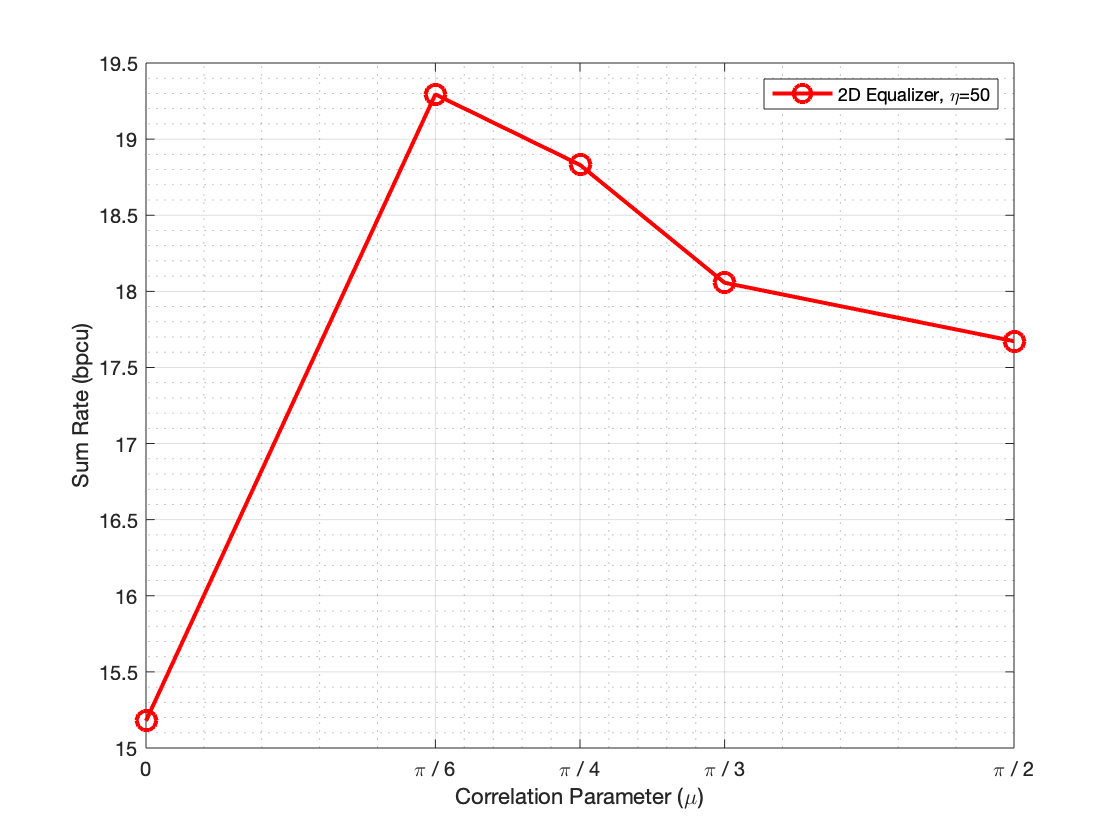



figure;
plot(mu, R5, style_2, 'DisplayName', name5, 'MarkerSize', 10);

xlabel(x_label_2, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(mu);
xticklabels({'0', '\pi / 6', '\pi / 4', '\pi / 3', '\pi / 2'})
xlim([mu(1), mu(sample)]);
legend();
grid on;
grid minor;

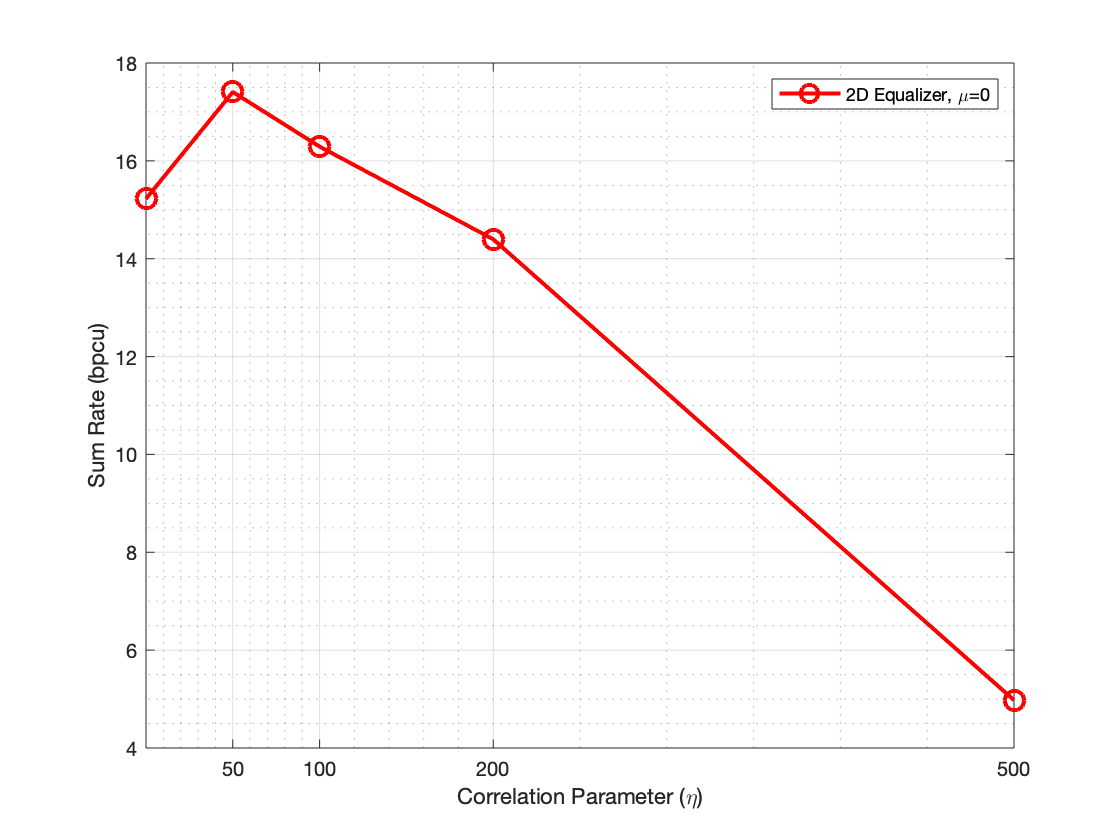



figure;
plot(eta, R6, style_2, 'DisplayName', name6, 'MarkerSize', 10);

xlabel(x_label_3, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(eta(2 : sample));
xlim([eta(1), eta(sample)]);
legend();
grid on;
grid minor;